依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

根据PCA取模板细胞

DataSet=TransferLearning.FullCalcium;

HeatCalcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig1J'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

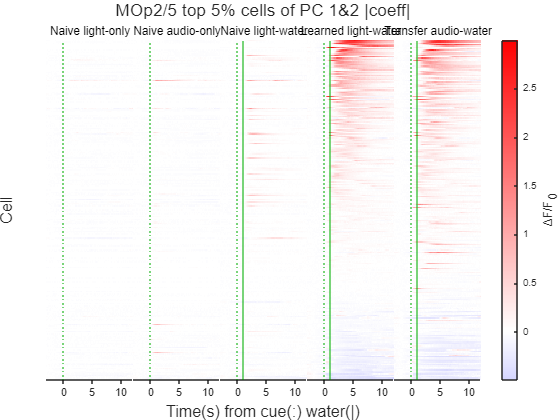

TemplateCalcium=HeatCalcium(ismember(HeatCalcium.CellUID,TransferLearning.TemplateCellUID(0.05,1:2)),:);
Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
NtatsData=UniExp.HeatmapSort(TemplateCalcium,"Learned_light_water").NTATS{:,:,["Naive_light_only","Naive_audio_only","Naive_light_water","Learned_light_water","Transfer_audio_water"]};
SubTitles=["Naive light-only","Naive audio-only","Naive light-water","Learned light-water","Transfer audio-water"];
[HeatmapLayout,Axes]=TransferLearning.BasicHeatmap(NtatsData,SubTitles,Colors,false,WaterLine=false);
for A=3:5
	xline(Axes(A),1,'-',Color=Colors(3,:));
end
title(HeatmapLayout,'MOp top 5% cells of PC 1&2 |coeff|');

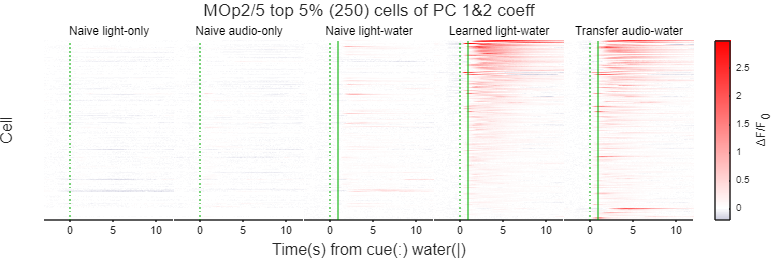

MATLAB.Graphics.FigureAspectRatio(3,1,1);
print(TransferLearning.ProjectPath('Fig1J.svg'),'-dsvg');

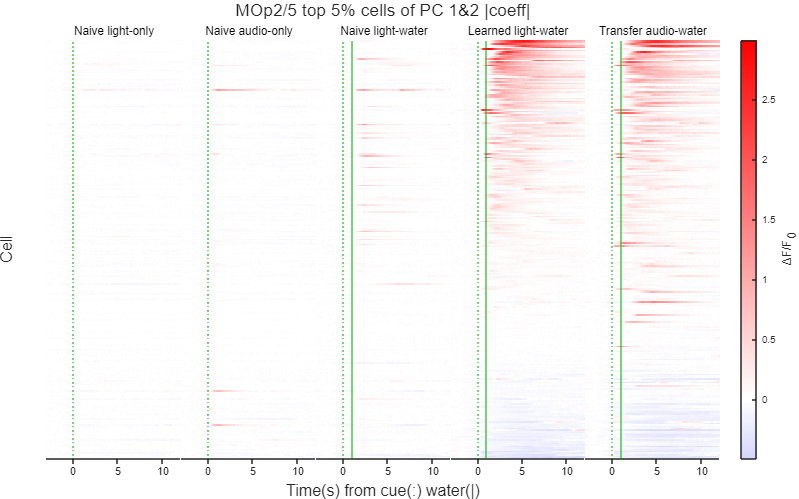

MATLAB.Graphics.FigureAspectRatio(8,5,2);
print(TransferLearning.ProjectPath('Fig1J.PPT.svg'),'-dsvg');

线图

[Mean,Sem]=MATLAB.DataFun.MeanSem(NtatsData,1);
Xs=linspace(-3,12,size(NaiveMean,2))';

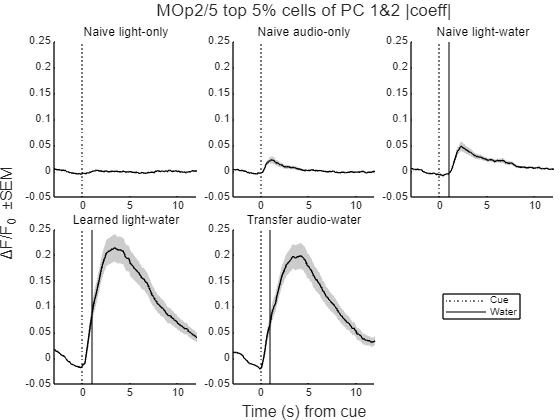

figure;
CurveLayout=tiledlayout(2,3,TileSpacing='tight',Padding='tight');
Axes=gobjects(5,1);
for A=1:5
	Axes(A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(Mean(:,:,A)',Sem(:,:,A)',X=Xs);
	CueLine=xline(0,':k');
	if A>2
		WaterLine=xline(1,'-k');
	end
	title(SubTitles(A));
end
L=legend([CueLine,WaterLine],["Cue","Water"]);
L.Layout.Tile=6;
MATLAB.UnifyYLims(Axes);
title(CurveLayout,'MOp2/5 top 5% cells of PC 1&2 |coeff|');
ylabel(CurveLayout,'ΔF/F_0 ±SEM');
xlabel(CurveLayout,'Time (s) from cue');
print(TransferLearning.ProjectPath('TemplateCurve.svg'),'-dsvg');